#  Segmentation optimization

by Rodrigo Migueles. Last Update: August 2023.

## Instructions

This Live Script is meant to help improve the segmentation results. If you do not have any segmentation done yet, it can also help you go step by step through the segmentation process, but it is more efficient to start with a segmentation using the default parameters and then tailor them to improve the results. 

**Warning**: It is not recommended to run the whole script, as different sections are meant for different situations and you should only run the sections that correspond to the situation you are in. 

Here are the potential situations:

- If you have already segmented an image stack, you are familiar with the parameters and have a clear idea of what you could do to improve the results, then go to the Quick Optimization section.

- If you have an overall good segmentation that needs improvements in some frames, then go to the Threshold Optimizaiton.

- If you have a very bad segmentation that requires serious improvements, go to the Detailed Optimization.

## Preview

Use the Frame slider to navigate through the stack.

if ~exist('stack', 'var')
    [file_name, file_path] = uigetfile('*.tif');
    stack = readTIFFstack([file_path, file_name]);
end
n_frames = size(stack,3);
frame = 1;
image = stack(:,:,frame);

Original Image

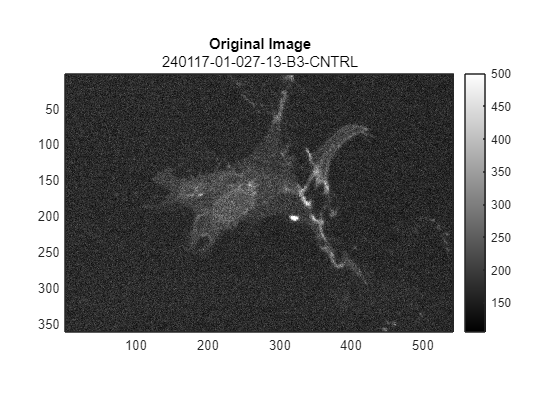

figure; imagesc(image); colormap gray; axis image; cb = colorbar; 
title('Original Image');
subtitle(fileKey);
cLimit = cb.Limits; cLimMax = cLimit(2);
cLim = 500; cLimit(2) = cLim;
clim(cLimit);

Original Image Histogram

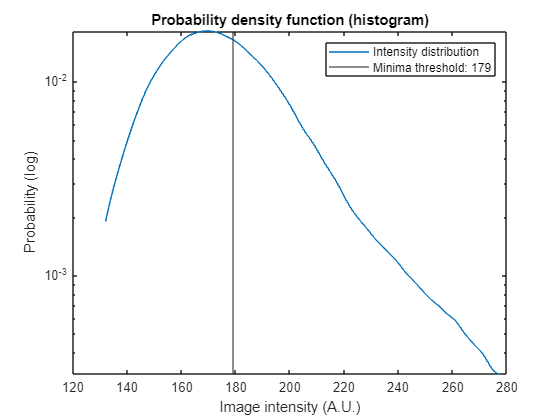

plotSegmentationHistogram(image, Options.Preprocessing, siteIndex, cropIndex, frame, 'y');
hold on;

% xline(Options.Preprocessing(siteIndex).Threshold(frame, max(cropIndex,1)), 'Color', 'r');
% ax = gca; 
% lg = ax.Legend; 
% lg.String{1,3} = ['Minima threshold: ', num2str(Options.Preprocessing(siteIndex).Threshold(frame, max(cropIndex,1)))];

Current segmentation

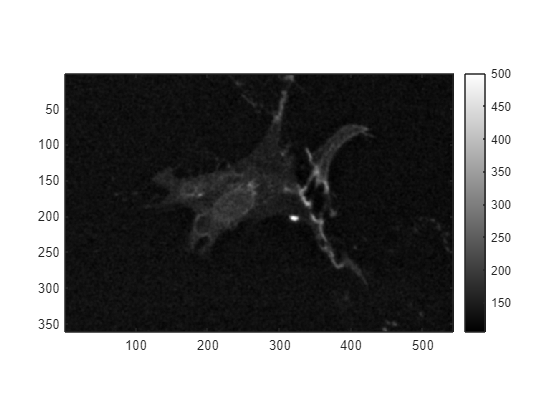

[blurred_image, mask, SegOpt] = getCellMask(image, Options.Preprocessing, siteIndex, cropIndex);
figure; imagesc(blurred_image); axis image; colorbar; colormap gray; clim(cLimit);

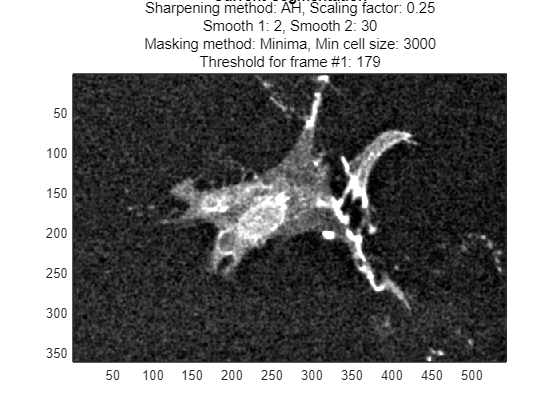

figure; outlined_img = DrawMaskOutline(blurred_image, mask); 
imagesc(outlined_img); axis image; title('Current Segmentation');
subtitle({['Sharpening method: ', num2str(Options.Preprocessing(siteIndex).SharpenMethod),...
', Scaling factor: ', num2str(Options.Preprocessing(siteIndex).ScalingFactor)];...
['Smooth 1: ', num2str(Options.Preprocessing(siteIndex).Smooth1),...
', Smooth 2: ', num2str(Options.Preprocessing(siteIndex).Smooth2)];...
['Masking method: ', Options.Preprocessing(siteIndex).MaskMethod,...
', Min cell size: ', num2str(Options.Preprocessing(siteIndex).MinCellSize)];...
['Threshold for frame #', num2str(frame),': ', num2str(Options.Preprocessing(siteIndex).Threshold(frame,max(cropIndex,1)))]});

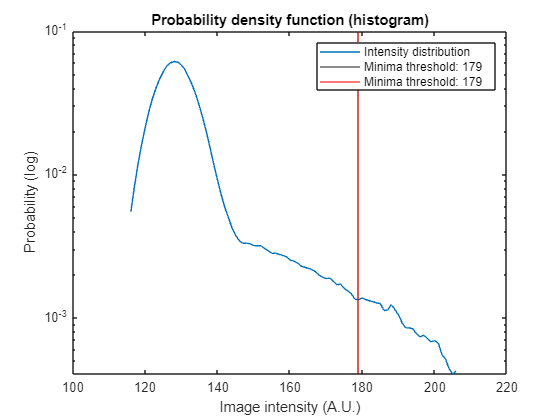

plotSegmentationHistogram(blurred_image, Options.Preprocessing, siteIndex, cropIndex, frame, 'y');
xline(Options.Preprocessing(siteIndex).Threshold(frame, max(cropIndex, 1)), 'Color', 'r');
ax = gca; lg = ax.Legend; 
lg.String{1,3} = ['Minima threshold: ', num2str(Options.Preprocessing(siteIndex).Threshold(frame, max(cropIndex,1)))];

## Quick Optimization

SharpenMethod = 'AH';
ScalingFactor= 0.15;
Smooth1 = 2;
Smooth2 = 3;

MaskMethod = 'Minima';
PeakJump = 0;
MinPeakSize = 0.005;
PeakNoise =0.005;
MinCellSize = 1000;

 
SegOpt(siteIndex).SharpenMethod = SharpenMethod;
SegOpt(siteIndex).ScalingFactor = ScalingFactor;
SegOpt(siteIndex).Smooth1 = Smooth1;
SegOpt(siteIndex).Smooth1 = Smooth2;
SegOpt(siteIndex).MaskMethod = MaskMethod;
SegOpt(siteIndex).PeakJump = PeakJump;
SegOpt(siteIndex).MinPeakSize = MinPeakSize;
SegOpt(siteIndex).PeakNoise = PeakNoise;
SegOpt(siteIndex).MinCellSize = MinCellSize;

image = stack(:,:,frame); clear blurred_image;
[blurred_image, mask, SegOpt] = getCellMask(image, SegOpt, siteIndex);
figure; outlined_img = DrawMaskOutline(blurred_image, mask); 
imshow(outlined_img); axis image;
warning off; plotSegmentationHistogram(image, SegOpt, siteIndex, cropIndex, frame);

disp(['Current sharpening method: ', num2str(SegOpt(siteIndex).SharpenMethod)]);
disp(['Current scaling factor: ', num2str(SegOpt(siteIndex).ScalingFactor)]);
disp(['Current Smooth 1: ', num2str(SegOpt(siteIndex).Smooth1)]);
disp(['Current Smooth 2: ', num2str(SegOpt(siteIndex).Smooth2)]);
disp(['Current masking method: ', SegOpt(siteIndex).MaskMethod]);
disp(['Current min cell size: ', num2str(SegOpt(siteIndex).MinCellSize)]);
disp(['Current threshold for frame #', num2str(frame),': ', num2str(SegOpt(siteIndex).Threshold(frame,1))]);

## Threshold Optimization

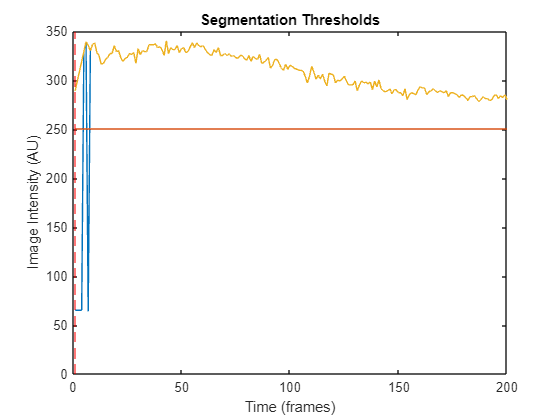

figure; ax = gca; plot(SegOpt(siteIndex).Threshold(:, max(cropIndex,1))); ylimits = ax.YLim; hold on;
x = 1:n_frames;
m =0; % Slope
max_b = max(SegOpt(siteIndex).Threshold)*2;
b =250; % Intercept
slope_y = m*x + b;
plot(slope_y); 
title('Segmentation Thresholds'); xlabel('Time (frames)'); ylabel('Image Intensity (AU)');
xline(frame, '--r');
ylimits(1) = 0; ax.YLim = ylimits;
ax.XLim(2) = x(end);

deleteFrames = [x(SegOpt(siteIndex).Threshold(1:metadata(file).n_frames, max(cropIndex,1)) < slope_y')];
SegOpt(siteIndex).Threshold = double(SegOpt(siteIndex).Threshold);
for dFrame = deleteFrames
    SegOpt(siteIndex).Threshold(dFrame, max(cropIndex,1)) = NaN;
end
nan_y = inpaint_nans(SegOpt(siteIndex).Threshold(:, max(cropIndex,1)));
% nan_y(70:75,1) = repmat(nan_y(69,1), [6,1]);
plot(nan_y); 
plot(frame, SegOpt(siteIndex).Threshold(frame, max(cropIndex,1)), 'ob');
hold off; 

use_slope = true;
if use_slope
    SegOpt(siteIndex).MaskMethod = 'Manual'; 
    SegOpt(siteIndex).Threshold(1:metadata(file).n_frames, max(cropIndex,1)) = slope_y';
%     SegOpt(siteIndex).Threshold(6:end) = y(6:end)';
end

use_inpaint = true;
if use_inpaint
    SegOpt(siteIndex).MaskMethod = 'Manual'; 
    SegOpt(siteIndex).Threshold(:, max(cropIndex,1)) = nan_y;
end

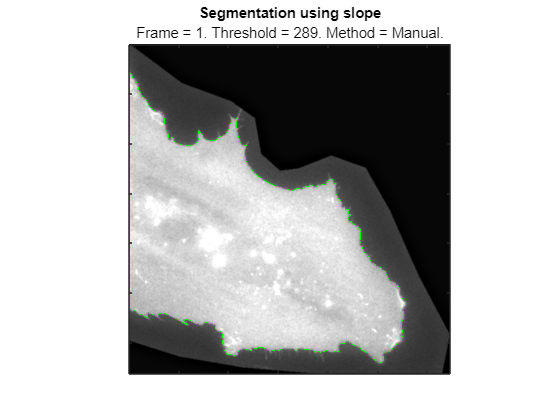

[blurred_image, mask, SegOpt] = getCellMask(image, SegOpt, siteIndex, cropIndex);
figure; ax = gca;
outlined_img = DrawMaskOutline(blurred_image, mask); 
imagesc(outlined_img); axis image; colormap("gray");
title(ax, 'Segmentation using slope');
subtitle(['Frame = ', num2str(frame),...
'. Threshold = ', num2str(SegOpt(siteIndex).Threshold(frame,max(cropIndex,1))),...
'. Method = ', SegOpt(siteIndex).MaskMethod, '.']);
ax.XTickLabel = []; ax.YTickLabel = [];

use_manual_mode = true;
if use_manual_mode
    SegOpt(siteIndex).MaskMethod = 'Manual';
else
    SegOpt(siteIndex).MaskMethod = Options.Preprocessing(siteIndex).MaskMethod;
end

approved = true;
if approved
    Options.Preprocessing = SegOpt;
    Options.Preprocessing(siteIndex).Threshold;
    disp('Segmentation Approved!');
end

Segmentation Approved!


## Detailed Optimization

The goal consists in  image segmentation of the cell from the background. This is a critical step for the edge dynamics analysis. 

The process can be divided into three steps: sharpening, segmentation and morphological operations. 

Since there are significant differences between the cell videos, it is not easy to find a combination of sharpening and segmentation parameters that fits all videos of a single file. 

Let's begin by loading an image into the Workspace and displaying it.

image = stack(:,:,frame);
hold off; imagesc(image); colorbar; colormap('gray'); axis image;
PixMinMax = double([round(prctile(image(:),1)), round(prctile(image(:),99))]); caxis([PixMinMax(1), PixMinMax(2)]);
histogram(image);

### **Sharpening:**

The current strategy (a home-made algorithm) and the MATLAB built-in `imsharpen` function both use the *unsharp masking* procedure in which “an image is sharpened by subtracting a blurred (unsharp) version of the image from itself”. 

#### *Home-made version*

In the home-made version the first step is to create two blurred versions of the image: a slightly blurred version (`imSmooth1`) and a severely blurred one (`image_lpf` for low-pass filter). 

`imSmooth1=imfilter(image,fspecial('disk',2),'replicate');`

imSmooth1=imfilter(image,fspecial('disk',Smooth1),'replicate');
imshow(imSmooth1, [PixMinMax(1), PixMinMax(2)]); axis image

`image_lpf=imfilter(imSmooth1,fspecial('disk',30),'symmetric');`

image_lpf=imfilter(imSmooth1,fspecial('disk',Smooth2),'symmetric');
imshow(image_lpf, [PixMinMax(1), PixMinMax(2)]); axis image

The second step is to subtract the severely blurred version (scaled by a factor <1) from the slightly blurred one. 

`imSmooth2=imSmooth1-image_lpf*0.25; % arbitrary scaling factor - adjust as needed`

imSmooth2 = imSmooth1-image_lpf*ScalingFactor; 
imshow(imSmooth2, [PixMinMax(1), PixMinMax(2)]); axis image

This scaling factor depends on how much "halo" is seen around the cell edge and needs to be adjusted accordingly for each video.

#### *Built-in function *

The built-in `imsharpen` function uses a similar technique but it uses a Gaussian filter instead of a disk-shaped filter and it requires at least two inputs: Radius and Amount.

sharpened_img = imsharpen(image);   
imshow(sharpened_img, [PixMinMax(1), PixMinMax(2)]); axis image 
figure; subplot(1,2,1); imshow(image, [PixMinMax(1), PixMinMax(2)]);
subplot(1,2,2); imshow(sharpened_img, [PixMinMax(1), PixMinMax(2)]);

figure;
[f,xi] = ksdensity(image(:), [PixMinMax(1): PixMinMax(2)]);
semilogy(xi,f); hold on
[pks,locs] = findpeaks(f,xi);

%filter peaks greater than 0.005
log_pks = pks> MinPeakSize; 
yline(MinPeakSize, '--r');
pks=pks(log_pks); locs=locs(log_pks);
plot((locs),pks,'k^','markerfacecolor',[1 0 0]);
% for sf = 0.1:0.2:0.9
%     imSmooth3 = sharpenImage_Hayer(image, sf);
%     [f,xi] = ksdensity(imSmooth3(:), 0:500);
%     plot(xi,f);
% end

[f,xi] = ksdensity(imSmooth2(:), [PixMinMax(1): PixMinMax(2)]);
semilogy(xi,f); hold on
[pks,locs]=findpeaks(f,xi);

%filter peaks greater than 0.005
log_pks=pks> MinPeakSize; 
pks=pks(log_pks); locs=locs(log_pks);
plot((locs),pks,'k^','markerfacecolor',[1 0 0]);

hold off

### **Image Segmentation:**

#### *Peak Jump*

The current method is based on the smoothening of the histogram of the sharpened image into a continuous curve followed by the location of peaks greater than a given threshold (typically > 0.005). 

% Histogram-based threshold determination
% find range of pixel values
PixMinMax=double([round(prctile(imSmooth2(:),1)), round(prctile(imSmooth2(:),99))]); % can also use zero for the bottom limit 
IntStep=ceil((PixMinMax(2)-PixMinMax(1))/300);  

%plot probability dist. of pixel intensities in the frame
[f,xi]=ksdensity(imSmooth2(:),0:2500); % can increase the range as much or as little as you want 
figure; plot(xi,f); hold on;  
[pks,locs]=findpeaks(f,xi);

%filter peaks greater than 0.005
log_pks=pks>0.005; 
pks=pks(log_pks); locs=locs(log_pks);
plot((locs),pks,'k^','markerfacecolor',[1 0 0]);

Since most of the videos contain isolated cells, the most part of the pixels contribute to the background so the greatest peak corresponds to the background and has usually a low value (< 100 levels of grey in 16-bit images). 

Once the peak located, the grey level at which the histogram reaches the 1% or 0.5% of the histogram's maximum (which usually corresponds to the peak's height). 

x_bgMax=locs(1,1); % picks the first peak (x-value of first peak)
[~,ind]=find(f>(0.01*pks(1)),1); % returns the first value of f greater than 0.5% of its max
x_1pct=xi(ind); % returns the corresponding intensity value
xline(x_1pct, '--');
bgWidth=x_bgMax-x_1pct; % estimates the width of the background peak
xline((x_bgMax+bgWidth), '--');

This value is considered to be the peak's left foot and the distance from this value to the peak location (peak radius) is used to estimate the peak's width as twice the distance.

Once the peak's width determined, the peak radius is multiplied by a jumping factor (usually an integer between 2 and 6) and added to the peaks location to determine the threshold. 

% Determine threshold for distinction between foreground/background (most important part of the code here)
threshSeg = (x_bgMax+(peak_jump)*bgWidth) % number here adjustable: if having trouble with segmentation adjust based on fg/bg separation

xline(threshSeg); % again just for visualization
hold off; 

This clever strategy has however two main caveats. The first is that it is not informed by the shape of the histogram to the right of the background peak: the peak juming is a leap of faith. The second is that finding an appropriate jumping factor is therefore an user-adjusted task and depends a lot on a subjective estimation.

mask_init=imSmooth2>threshold;
minCellSize = 6000;
mask=bwareaopen(mask_init,minCellSize);
mask_filled1=imfill(mask,'holes');
holes=mask_filled1 & ~mask;
bigholes = bwareaopen(holes,minCellSize);
smallholes= holes & ~bigholes;
maskFinal = mask | smallholes;
mask2 = imopen(maskFinal, strel('disk', 3)); %get rid of tiny fibers
maskFinal = maskFinal & mask2;

masked_image = double(image);
masked_image(~maskFinal) = nan; 
imshow(masked_image);
outlined_img = DrawMaskOutline(image, maskFinal, [0,1,0]);
imshow(outlined_img);

#### *Minima Location*

Assuming that we have a bimodal distribution with a background-dominated fraction of pixels, it is intuitive to think that there must be a minima between these two peaks (background and cell).

However, in some cases of severe photobleaching, the histogram of the cell can merge into the background peak, creating a shoulder with no minima between the two. Also, in cases in which the histogram has flat sections, several minima can be found, which makes it hard to select which minima to use. I have tried selecting the first minima after the peak's location. 

[lmin] = islocalmin(f, 'MaxNumExtrema', 3);
threshMinAfterPeak = xi(lmin) > locs(1);
threshMin = xi(lmin);
threshMin = threshMin(threshMinAfterPeak);
threshMin = threshMin(1)
mask_init=imSmooth2>threshMin;
minCellSize = 6000;
mask=bwareaopen(mask_init,minCellSize);
mask_filled1=imfill(mask,'holes');
holes=mask_filled1 & ~mask;
bigholes = bwareaopen(holes,minCellSize);
smallholes= holes & ~bigholes;
maskFinal = mask | smallholes;

masked_image = double(image);
masked_image(~maskFinal) = nan; 
imagesc(masked_image);
outlined_img = DrawMaskOutline(image, maskFinal, [0,1,0]);
imshow(outlined_img);


#### *Logarithmic Otsu*

multithresh(image)
threshOtsu = multithresh(imSmooth2)
mask_init=imSmooth2>threshOtsu;
minCellSize = 6000;
mask=bwareaopen(mask_init,minCellSize);
mask_filled1=imfill(mask,'holes');
holes=mask_filled1 & ~mask;
bigholes = bwareaopen(holes,minCellSize);
smallholes= holes & ~bigholes;
maskFinal = mask | smallholes;

masked_image = double(image);
masked_image(~maskFinal) = nan; 
imagesc(masked_image); axis image;
outlined_img = DrawMaskOutline(image, maskFinal, [0,1,0]);
imshow(outlined_img); axis image;

First 

rawMem = log(double(imSmooth2));
thresh = multithresh(rawMem)
[g,li] = ksdensity(rawMem(:));
figure; plot(li,g); hold on;  
xline(thresh); hold off;

### **Masking**

Once the threshold has been determined, the image can be masked using `imbinarize. `

mem_mask = imbinarize(imSmooth2, threshOtsu);
imshow(mem_mask); axis square
outlined_img = DrawMaskOutline(imSmooth2, maskFinal, [0,1,0]);
imshow(outlined_img); axis image;

However, chances are that the resulting mask is still somewhat fuzzy or noisy, which can be potentially fixed using morphological operations. 

### **Morphological operations**

The first thing we can do is to remove small debris in the background.

mem_mask = bwareaopen(maskFinal, 1000); %remove small objects
imshow(mem_mask); axis square

Now we can fill in the holes inside the cell.

mem_mask = imfill(mem_mask,'holes');
imshow(mem_mask);

Get rid of the fibers

mem_mask2 = imopen(mem_mask,strel('disk',3)); 
imshow(mem_mask2);

Compare

imshow(mem_mask-mem_mask2);

Now select the intersection

mem_mask = mem_mask & mem_mask2;
imshow(mem_mask);
% outline = bwperim(mem_mask, 8);
% imshow(outline);

Let's see what that looks overlayed on top of the original picture.

outlined_img = DrawMaskOutline(imSmooth2, mem_mask, [0,1,0]);
imshow(outlined_img);

load([OneDrive, '\Metadata\201105_metadata.mat']);

[n_files, files_to_analyze, n_sites_per_file, sites] = selectWhich(metadata, 'custom');

TIFFStacks_path = [root, 'TIFF Stacks', filesep];
output_path = OneDrive;
for file = files_to_analyze
    for site  = sites(file, 1:n_sites_per_file)
        disp([num2str(char(metadata(file).file_name)), '-0', num2str(site)])
        stack_path = [TIFFStacks_path, ...
            num2str(char(metadata(file).file_name)), '-0', num2str(site), '.tif'];
        warning off
        stack = readTIFFstack(stack_path);
        image = stack(:, :, metadata(file).n_frames);
        
        f = figure
        axis tight
        i = 1;

        for scaling_factor = [0.2, 0.3, 0.4, 0.5, 0.6, 0.7]
            for peak_jump = [2, 3, 4, 5, 6, 7]
                
                subplot(6, 6, i)
                title(['SF = ', num2str(scaling_factor), ', PJ = ', num2str(peak_jump)])

                minCellSize = 2000;
                
                imSmooth1 = imfilter(image,fspecial('disk',2),'replicate');
                image_lpf = imfilter(imSmooth1,fspecial('disk',20),'symmetric');
                imSmooth2 = imSmooth1 - image_lpf*scaling_factor;

                % Histogram-based threshold determination
                % find range of pixel values
                PixMinMax=double([round(prctile(imSmooth2(:),1)), round(prctile(imSmooth2(:),99))]); % can also use zero for the bottom limit 
                IntStep=ceil((PixMinMax(2)-PixMinMax(1))/300);  

                %plot probability dist. of pixel intensities in the frame
                [f,xi]=ksdensity(imSmooth2(:),-3000:3000); % can increase the range as much or as little as you want 
                %figure; plot(xi,f); hold on;  
                [pks,locs]=findpeaks(f,xi);

                %filter peaks greater than 0.005
                log_pks=pks>0.01; 
                pks=pks(log_pks); locs=locs(log_pks);
                %plot((locs),pks,'k^','markerfacecolor',[1 0 0]);


                x_bgMax=locs(1,1); % picks the first peak (x-value of first peak)
                [~,ind]=find(f>(0.01*pks(1)),1); % returns the first value of f greater than 0.5% of its max
                x_1pct=xi(ind); % returns the corresponding intensity value
                bgWidth=x_bgMax-x_1pct; % estimates the width of the background peak

                %xline(x_bgMax+bgWidth); % to see how effective the estimation above of bg width is 

                %Determine threshold for distinction between foreground/background (most important part of the code here)
                threshSeg=(x_bgMax+(peak_jump)*bgWidth); % number here adjustable: if having trouble with segmentation adjust based on fg/bg separation

                % xline(threshSeg,'--'); % again just for visualization
                % hold off; 




                % masks the picture, then removes small areas of
                % background less than 200 pixels surrounded by cell (usually mistakes);
                mask_init = imSmooth2 > threshSeg;
                mask = bwareaopen(mask_init, minCellSize);
                mask_filled1 = imfill(mask, 'holes');
                holes = mask_filled1 & ~mask;
                bigholes = bwareaopen(holes, 200);
                smallholes = holes & ~bigholes;
                maskFinal = mask | smallholes;

                % get centroid coordinates
%                 objects = regionprops(maskFinal,'BoundingBox','Area','Centroid','Perimeter','PixelIdxList','PixelList');
%                 objects = objects(arrayfun(@(x) x.Area>minCellSize,objects));
%                 %objects=objects(arrayfun(@(x) x.Area<maxCellSize,objects));
% 
%                 cellCoors(:,1)=vect(arrayfun(@(x) x.Centroid(1),objects));
%                 cellCoors(:,2)=vect(arrayfun(@(x) x.Centroid(2),objects));
%                 cellCoors(:,3)=vect(arrayfun(@(x) x.Area,objects));
%                 cellCoors(:,4)=vect(arrayfun(@(x) x.Perimeter,objects));

%                 outline = bwperim(maskFinal, 8);
                outlined_img = DrawMaskOutline(image, maskFinal);
                imshow(outlined_img, [0, 900]);
                
                i = i + 1;
                
            end
        end
        ax = gca;
        fig = gcf;
        exportgraphics(fig, [output_path, num2str(char(metadata(file).file_name)), '-0', num2str(site), '_SegmentationOptimization.png']);
        savefig(fig, [output_path, num2str(char(metadata(file).file_name)), '-0', num2str(site), '_SegmentationOptimization.fig'], 'compact');
        
    end
end


% Histogram-based threshold determination
% find range of pixel values
PixMinMax=double([round(prctile(imSmooth2(:),1)), round(prctile(imSmooth2(:),99))]); % can also use zero for the bottom limit 
IntStep=ceil((PixMinMax(2)-PixMinMax(1))/300);  

%plot probability dist. of pixel intensities in the frame
[f,xi]=ksdensity(imSmooth2(:),0:2500); % can increase the range as much or as little as you want 
figure; 
plot(xi,f); 
hold on;  
[pks,locs]=findpeaks(f,xi);

%filter peaks greater than 0.005
log_pks=pks>0.005; 
pks=pks(log_pks); locs=locs(log_pks);
plot((locs),pks,'k^','markerfacecolor',[1 0 0]);
